% Modelling ML

clear; clc; % Clear workspace

% Load train and test data
train = readtable('train.csv');
test = readtable('test.csv');

% Convert to matrix
train = train{:,:};
test = test{:,:};

% Split into target and features 
X_train = train(:, 2:end);
y_train = train(:, 1);

X_test = test(:, 2:end);
y_test = test(:, 1);


% Load oversampled train data
X_train_SMOTE = readtable('X_train_SMOTE.csv');
y_train_SMOTE = readtable('y_train_SMOTE.csv');

X_train_SMOTE = X_train_SMOTE{:,:};
y_train_SMOTE = y_train_SMOTE{:,:};

rng(1) % for reproducability

% ********** 1) Train / Test Baseline Models **********

% 1a) Baseline Decision Tree with default parameters
% Train
dt_base = fitctree(X_train, y_train, 'Reproducible', 1, 'prior', 'empirical', 'MaxNumSplits', 10, 'MinLeafSize', 1);
% Evaluate baseline tree
test_model(dt_base, X_test, y_test)

% 1b) Baseline KNN
% Train
knn_base = fitcknn(X_train, y_train, 'Prior', 'empirical', 'NumNeighbors', 1, 'Distance', 'euclidean', 'DistanceWeight', 'equal'); 
% Evaluate baseline knn
test_model(knn_base, X_test, y_test)

% ********** 2) Hyperparameter Tuning Models (CV = k-fold, loss = accuracy) **********

% CV SPLITS: Define a random partition of data (fixes the train and validation set)
[nrow, ncol] = size(X_train);
c = cvpartition(nrow,'KFold', 20);

% DECISION TREE: Define vars and range
prior = optimizableVariable('prior', {'uniform','empirical'},'Type','categorical'); % default: 'empirical'
MaxNumSplit = optimizableVariable('MaxNumSplit',[1, 30],'Type','integer');  % default: 10
MinLeafSize = optimizableVariable('MinLeafSize', [1, 30], 'Type', 'integer');  % default: 1

ParamsDT = [prior, MaxNumSplit, MinLeafSize];

% KNN: Define vars and range
prior = optimizableVariable('prior', {'uniform','empirical'},'Type','categorical'); % default: 'empirical'
n = optimizableVariable('n',[1,20],'Type','integer'); % defualt: 1
dst = optimizableVariable('dst', {'euclidean', 'cosine', 'correlation'},'Type','categorical'); % default: euclidean
dstWeight = optimizableVariable('dstWeight', {'equal','inverse', 'squaredinverse'},'Type','categorical');  % default: equal

ParamsKNN = [prior; n; dst; dstWeight];

% 2a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = accuracy)
% 2a-i) Define loss function
loss = @(params)kfoldLoss(fitctree(X_train, y_train, 'CVPartition', c, 'Reproducible', 1,...
                                     'prior', char(params.prior), ...
                                     'MaxNumSplits',params.MaxNumSplit, ...
                                     'MinLeafSize',params.MinLeafSize));

% 2a-ii) Optimize model
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);
% 2a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'Reproducible', 1,...
    'prior', char(z.prior), ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 2a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

% 2b) KNN: Bayesian Optimization (CV = k-fold, loss = accuracy)
% 2b-i) Define loss function
loss = @(params)kfoldLoss(fitcknn(X_train, y_train, 'CVPartition', c, ...
            'prior', char(params.prior), ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst), ...
            'DistanceWeight',char(params.dstWeight)));

% 2b-ii) Optimize model
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);
% 2b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, ...
    'prior', char(z.prior), ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst), ...
    'DistanceWeight',char(z.dstWeight));

% 2b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

% ********** 3) Hyperparameter Tuning Models (CV = k-fold, loss = f-beta) **********

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |     0.99265 |     0.83076 |     0.99265 |     0.99265 |    empirical |           24 |            5 |
|    2 | Best   |     0.92952 |     0.46626 |     0.92952 |     0.93462 |      uniform |            2 |           17 |
|    3 | Best   |     0.90319 |      0.6164 |     0.90319 |     0.90323 |      uniform |            9 |           25 |
|    4 | Accept |           1 |      0.4376 |     0.90319 |     0.90321 |    empirical |            2 |           11 |
|    5 | Accept |     0.90729 |     0.79646 |   

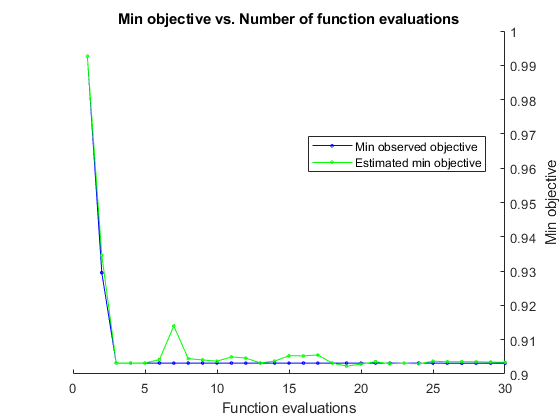


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 28.9948 seconds
Total objective function evaluation time: 20.4876

Best observed feasible point:
     prior     MaxNumSplit    MinLeafSize
    _______    ___________    ___________

    uniform        10              1     

Observed objective function value = 0.90314
Estimated objective function value = 0.90346
Function evaluation time = 0.61191

Best estimated feasible point (according to models):
     prior     MaxNumSplit    MinLeafSize
    _______    ___________    ___________

    uniform        12              1     

Estimated objective function value = 0.90341
Estimated function evaluation time = 0.63181



% 3a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = f-beta)
% 3a-i) Define loss function
loss = @(params)fb_loss_dt_cv(params,X_train,y_train, c); % see helper function

% 3a-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

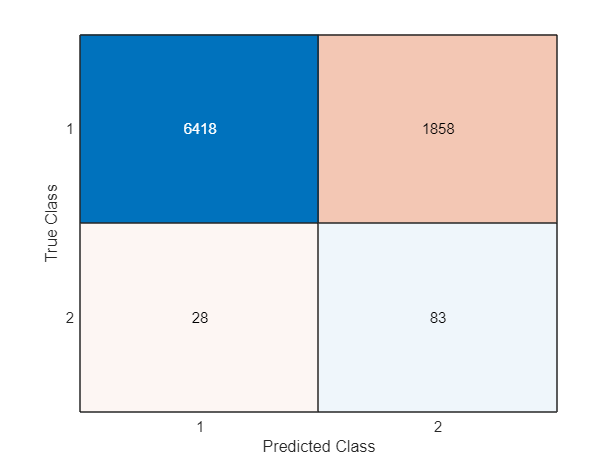

accuracy = 0.7751

precision = 0.0428

recall = 0.7477

specificity = 0.7755

fb = 0.0809


% 3a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'Reproducible', 1, ...
    'prior', char(z.prior), ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 3a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |            n |          dst |    dstWeight |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |
|===================================================================================================================================|
|    1 | Best   |     0.91827 |      5.4574 |     0.91827 |     0.91827 |      uniform |            6 |    euclidean |      inverse |
|    2 | Accept |     0.93457 |       5.505 |     0.91827 |     0.91892 |      uniform |           18 |  correlation |      inverse |
|    3 | Accept |     0.99626 |      5.9615 |     0.91827 |     0.94968 |    empirical |           10 |    euclidean |      inverse |
|    4 | Accept |           1 |      5.0811 |     0.91827 |   

|    6 | Accept |     0.93461 |      6.2011 |     0.91827 |      0.9249 |      uniform |           18 |       cosine |        equal |
|    7 | Accept |     0.96527 |      6.0573 |     0.91827 |     0.92461 |    empirical |            6 |       cosine | squaredinver |
|    8 | Accept |      0.9285 |      5.0542 |     0.91827 |      0.9191 |      uniform |            7 |       cosine |        equal |
|    9 | Accept |     0.93045 |      4.7661 |     0.91827 |     0.91904 |      uniform |           19 |       cosine | squaredinver |
|   10 | Accept |      0.9772 |       4.733 |     0.91827 |     0.92022 |    empirical |           15 |       cosine | squaredinver |
|   11 | Best   |      0.9154 |      4.9381 |      0.9154 |     0.91752 |      uniform |           20 |    euclidean |      inverse |
|   12 | Accept |      0.9154 |      4.8657 |      0.9154 |      0.9154 |      uniform |           20 |    euclidean |      inverse |
|   13 | Accept |     0.93363 |      4.6945 |      0.9154 |   

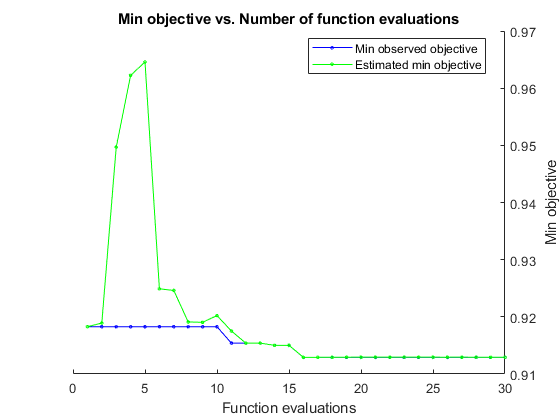


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 719.6642 seconds
Total objective function evaluation time: 153.9195

Best observed feasible point:
     prior     n        dst       dstWeight
    _______    __    _________    _________

    uniform    10    euclidean      equal  

Observed objective function value = 0.91291
Estimated objective function value = 0.91296
Function evaluation time = 4.9075

Best estimated feasible point (according to models):
     prior     n        dst       dstWeight
    _______    __    _________    _________

    uniform    14    euclidean      equal  

Estimated 

% 3b) KNN: Bayesian Optimization (CV = k-fold, loss = f-beta)
% 3b-i) Define loss function
loss = @(params)fb_loss_knn_cv(params,X_train,y_train, c); % see helper function

% 3b-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

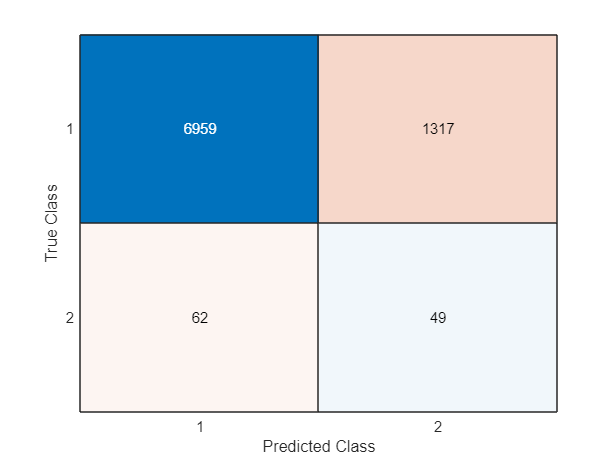

accuracy = 0.8356

precision = 0.0359

recall = 0.4414

specificity = 0.8409

fb = 0.0664


% 3b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, ...
    'prior', char(z.prior), ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst), ...
    'DistanceWeight',char(z.dstWeight));

% 3b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

% ********** 4) Hyperparameter Tuning Models (CV = statify, loss = f-beta) **********

% CV SPLITS (Stratified)
c_strat = cvpartition(y_train,'KFold', 20, 'Stratify', true);

% 4a) Decision Tree: Bayesian Optimization (CV = statify, loss = f-beta)
% 4a-i) Define loss function
loss = @(params)fb_loss_dt_cv(params,X_train,y_train, c_strat); % see helper function

% 4a-ii) Optimize model
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

% 4a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'Reproducible', 1, ...
    'prior', char(z.prior), ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 4a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

% 4b) KNN: Bayesian Optimization (CV = statify, loss = f-beta)
disp('***** Hyperparameter Tuning KNN (CV = statify, loss = f-beta) *****')

% 4b-i) Define loss function
loss = @(params)fb_loss_knn_cv(params,X_train,y_train, c_strat) % see helper function

% 4b-ii) Optimize model
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

% 4b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, ...
    'prior', char(z.prior), ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst), ...
    'DistanceWeight',char(z.dstWeight));

% 4b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

% ********** 5) Hyperparameter Tuning Models (CV = k-fold, loss = f-beta, SMOTE) **********

% CV SPLITS SMOTE:
[nrow, ncol] = size(X_train_SMOTE);
c_SMOTE = cvpartition(nrow,'KFold', 20);

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |    0.090922 |      1.9941 |    0.090922 |    0.090922 |    empirical |           24 |            5 |
|    2 | Accept |     0.15148 |     0.92571 |    0.090922 |    0.095811 |      uniform |            2 |           17 |
|    3 | Accept |     0.10669 |      1.3297 |    0.090922 |    0.096049 |      uniform |            9 |           25 |
|    4 | Accept |     0.15148 |     0.91532 |    0.090922 |    0.090983 |    empirical |            2 |           11 |
|    5 | Accept |    0.094434 |      1.5662 |   

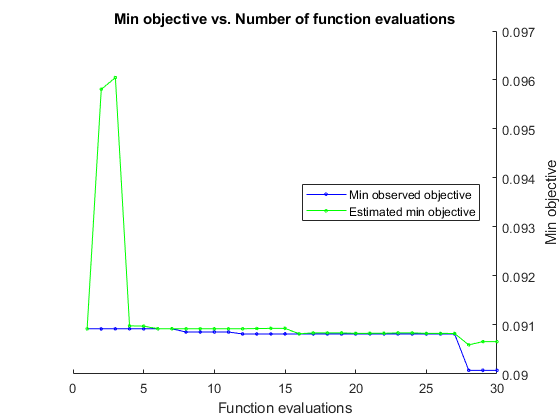


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 56.6317 seconds
Total objective function evaluation time: 48.1331

Best observed feasible point:
     prior     MaxNumSplit    MinLeafSize
    _______    ___________    ___________

    uniform        30              9     

Observed objective function value = 0.090075
Estimated objective function value = 0.090662
Function evaluation time = 2.1943

Best estimated feasible point (according to models):
     prior     MaxNumSplit    MinLeafSize
    _______    ___________    ___________

    uniform        30              9     

Estimated objective function value = 0.090662
Estimated function evaluation time = 2.114



% 5a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = f-beta, SMOTE)
% 5a-i) Define loss function
loss = @(params)fb_loss_dt_cv(params,X_train_SMOTE,y_train_SMOTE, c_SMOTE); % see helper function

% 5a-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

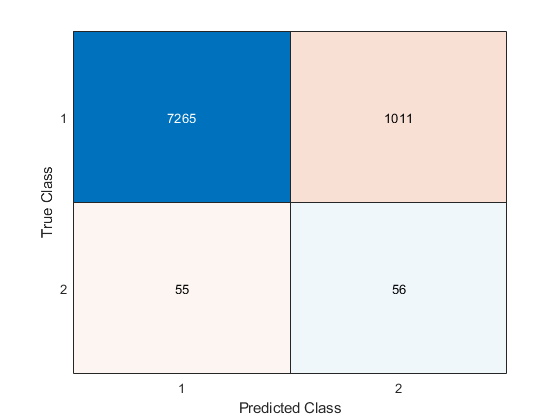

accuracy = 0.8729

precision = 0.0525

recall = 0.5045

specificity = 0.8778

fb = 0.0951


% 5a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train_SMOTE, y_train_SMOTE, 'Reproducible', 1, ...
    'prior', char(z.prior), ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 5a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |            n |          dst |    dstWeight |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |
|===================================================================================================================================|
|    1 | Best   |    0.032219 |      21.921 |    0.032219 |    0.032219 |      uniform |            6 |    euclidean |      inverse |
|    2 | Accept |    0.076668 |      20.582 |    0.032219 |    0.033986 |      uniform |           18 |  correlation |      inverse |
|    3 | Accept |    0.039773 |      21.988 |    0.032219 |    0.032223 |    empirical |           10 |    euclidean |      inverse |
|    4 | Accept |    0.057233 |      21.232 |    0.032219 |   

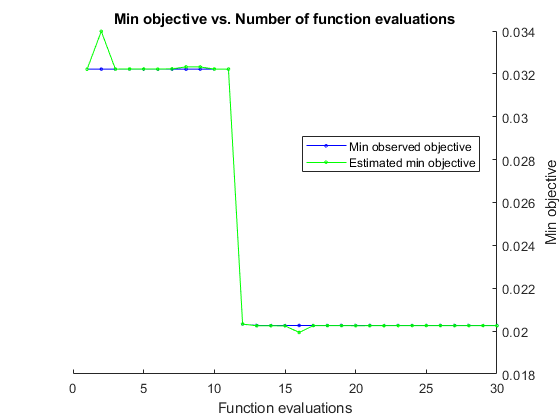


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 749.5778 seconds
Total objective function evaluation time: 712.6473

Best observed feasible point:
     prior     n       dst       dstWeight
    _______    _    _________    _________

    uniform    1    euclidean     inverse 

Observed objective function value = 0.020264
Estimated objective function value = 0.020255
Function evaluation time = 32.1546

Best estimated feasible point (according to models):
     prior     n       dst       dstWeight
    _______    _    _________    _________

    uniform    1    euclidean     inverse 

Estimated obj

% 5b) KNN: Bayesian Optimization (CV = k-fold, loss = f-beta, SMOTE)
% 5b-i) Define loss function
loss = @(params)fb_loss_knn_cv(params,X_train_SMOTE, y_train_SMOTE, c_SMOTE); % see helper function

% 5b-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

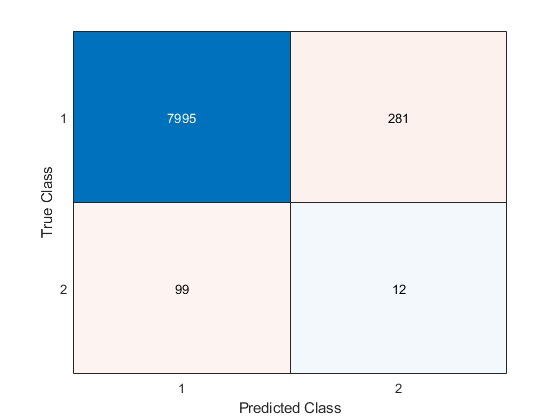

accuracy = 0.9547

precision = 0.0410

recall = 0.1081

specificity = 0.9660

fb = 0.0594


% 5b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train_SMOTE, y_train_SMOTE, ...
    'prior', char(z.prior), ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst), ...
    'DistanceWeight',char(z.dstWeight));

% 5b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

% ********** 6) Hyperparameter Tuning Models (CV = k-fold, loss = accuracy, SMOTE) **********

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |        0.13 |      1.2986 |        0.13 |        0.13 |      uniform |            5 |           10 |
|    2 | Best   |      0.1039 |      1.6054 |      0.1039 |     0.10622 |      uniform |           16 |            7 |
|    3 | Accept |     0.15019 |     0.99029 |      0.1039 |     0.10391 |      uniform |            3 |           20 |
|    4 | Best   |    0.095253 |      1.7391 |    0.095253 |    0.095255 |      uniform |           26 |           13 |
|    5 | Accept |     0.10984 |      1.4138 |   

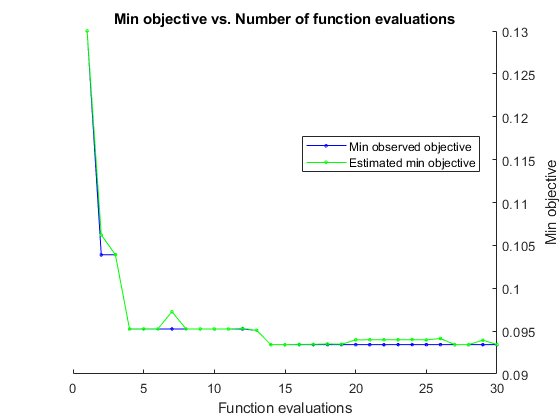


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 55.2093 seconds
Total objective function evaluation time: 44.5684

Best observed feasible point:
      prior      MaxNumSplit    MinLeafSize
    _________    ___________    ___________

    empirical        30             13     

Observed objective function value = 0.093421
Estimated objective function value = 0.093501
Function evaluation time = 1.825

Best estimated feasible point (according to models):
      prior      MaxNumSplit    MinLeafSize
    _________    ___________    ___________

    empirical        30             14     

Estimated objective function value = 0.093435
Estimated function evaluation tim

% 6a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = accuracy, SMOTE)
% 6a-i) Define loss function
loss = @(params)kfoldLoss(fitctree(X_train_SMOTE, y_train_SMOTE, 'CVPartition', c_SMOTE, 'Reproducible', 1,...
                                     'prior', char(params.prior), ...
                                     'MaxNumSplits',params.MaxNumSplit, ...
                                     'MinLeafSize',params.MinLeafSize));

% 6a-ii) Optimize model
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

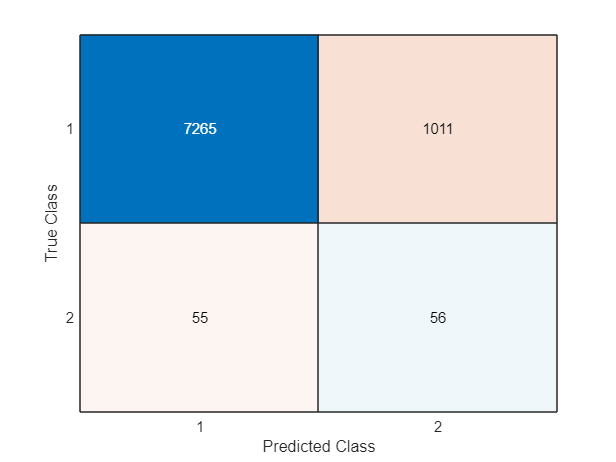

accuracy = 0.8729

precision = 0.0525

recall = 0.5045

specificity = 0.8778

fb = 0.0951

% 6a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train_SMOTE, y_train_SMOTE, 'Reproducible', 1,...
    'prior', char(z.prior), ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 6a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |            n |          dst |    dstWeight |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |
|===================================================================================================================================|
|    1 | Best   |    0.070883 |      20.744 |    0.070883 |    0.070883 |    empirical |           12 |       cosine |        equal |
|    2 | Best   |      0.0347 |      20.761 |      0.0347 |    0.036579 |    empirical |            3 |       cosine |      inverse |
|    3 | Accept |    0.076472 |      20.919 |      0.0347 |    0.041815 |      uniform |           14 |  correlation |      inverse |
|    4 | Best   |    0.030792 |      20.893 |    0.030792 |   

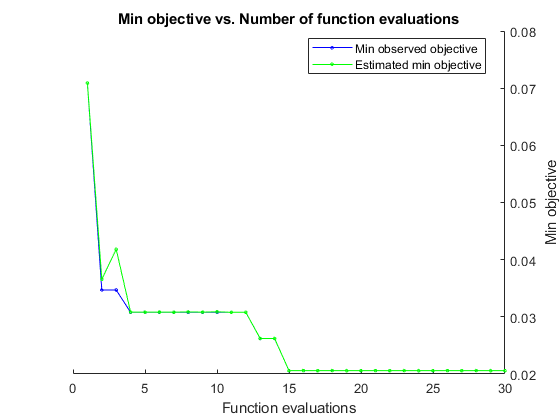


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 714.7906 seconds
Total objective function evaluation time: 677.4003

Best observed feasible point:
      prior      n       dst       dstWeight
    _________    _    _________    _________

    empirical    1    euclidean      equal  

Observed objective function value = 0.020583
Estimated objective function value = 0.020588
Function evaluation time = 20.3853

Best estimated feasible point (according to models):
     prior     n       dst         dstWeight   
    _______    _    _________    ______________

    uniform    1    euclidean    squaredi

% 6b) KNN: Bayesian Optimization (CV = k-fold, loss = accuracy, SMOTE)
% 6b-i) Define loss function
loss = @(params)kfoldLoss(fitcknn(X_train_SMOTE, y_train_SMOTE, 'CVPartition', c_SMOTE, ...
            'prior', char(params.prior), ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst), ...
            'DistanceWeight',char(params.dstWeight)));

% 6b-ii) Optimize model
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

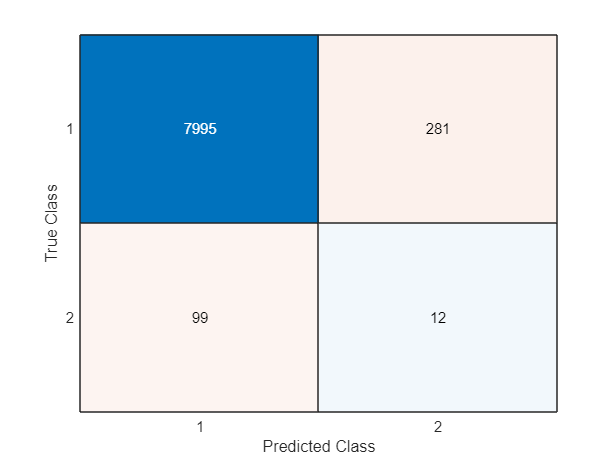

accuracy = 0.9547

precision = 0.0410

recall = 0.1081

specificity = 0.9660

fb = 0.0594

% 6b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train_SMOTE, y_train_SMOTE, ...
    'prior', char(z.prior), ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst), ...
    'DistanceWeight',char(z.dstWeight));

% 6b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

function test_model(model, X_test, y_test)
    y_pred = predict(model, X_test);
    cmat = confusionmat(y_test, y_pred);  % Confusion matrix
    confusionchart(cmat);
    [accuracy, precision, recall, specificity, fb] = binary_eval_metrics(y_test, y_pred) 
end

% Decision tree loss loss function CV
function fb = fb_loss_dt_cv(params, X_train, y_train, cv_part)
        % Train model with selected parameters
        model = fitctree(X_train, y_train, 'CVPartition', cv_part, 'Reproducible', 1,...
             'prior', char(params.prior), ...
             'MaxNumSplits',params.MaxNumSplit, ...
             'MinLeafSize',params.MinLeafSize);
               
        % Calculate F1 score
        y_pred = kfoldPredict(model);
        [~, ~, ~, ~, fb] = binary_eval_metrics(y_train, y_pred);
        fb = 1-fb;  % Convert to f1-"loss"
end

% KNN function CV
function fb = fb_loss_knn_cv(params, X_train, y_train, cv_part)
        model = fitcknn(X_train, y_train, 'CVPartition', cv_part, ...
            'prior', char(params.prior), ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst), ...
            'DistanceWeight',char(params.dstWeight));
        
        % Calculate F-beta score
        y_pred = kfoldPredict(model);   
        [~, ~, ~, ~, fb] = binary_eval_metrics(y_train, y_pred);
        fb = 1-fb;  % Convert to f1-"loss"
end

% Evaluation metrics for binary classification
function [acc, prec, rec, spec, fb] = binary_eval_metrics(y_test, y_pred)
    cmat = confusionmat(y_test, y_pred);
    tn = cmat(1,1);
    fn = cmat(2,1);
    tp = cmat(2,2);
    fp = cmat(1,2);

    % Statistics of interest for confusion matrix
    b = 1; % beta < 1 favours precision over recall.
    prec = tp / (tp + fp); % precision
    rec = tp / (tp + fn); % recall
    spec = tn / (tn + fp); % specificity
    acc = (tp + tn) / (tn + fn + tp + fp);
    fb = ((1+b^2)*tp) / ((1+b^2)*tp + b^2 * fp + fn); % (see https://en.wikipedia.org/wiki/F-score)
end
%#ok<*ASGLU,*NOPRT> 